# Exercise 5: Quantize the network using calibration data

Quantizing a deep neural network in MATLAB® requires calibration by exercising the network to determine the dynamic ranges of its weights, biases, and activations. After calibrating, you can validate the performance of the quantized network and inspect the reduction in size and performance (if any) of the network.

%% Quantize the pretrained network
qLocal = dlquantizer(net, ExecutionEnvironment="MATLAB");
calResults = calibrate(qLocal, xTrain) %#ok<NASGU>

calResults = 41×5 table
    Optimized Layer Name     Network Layer Name    Learnables / Activations     MinValue       MaxValue 
    _____________________    __________________    ________________________    ___________    __________

    "imageinput_Mean"          {'imageinput'}            "Mean"                     833.51        833.51
    "conv_1_Weights"           {'conv_1'    }            "Weights"                -0.97762       0.52027
    "conv_1_Bias"              {'conv_1'    }            "Bias"                -1.4333e-10    1.8934e-10
    "conv_2_Weights"           {'conv_2'    }            "Weights"                -0.38041       0.41233
    "conv_2_Bias"              {'conv_2'    }            "Bias"                -1.3349e-07    1.3161e-07
    "conv_3_Weights"           {'conv_3'    }            "Weights"    

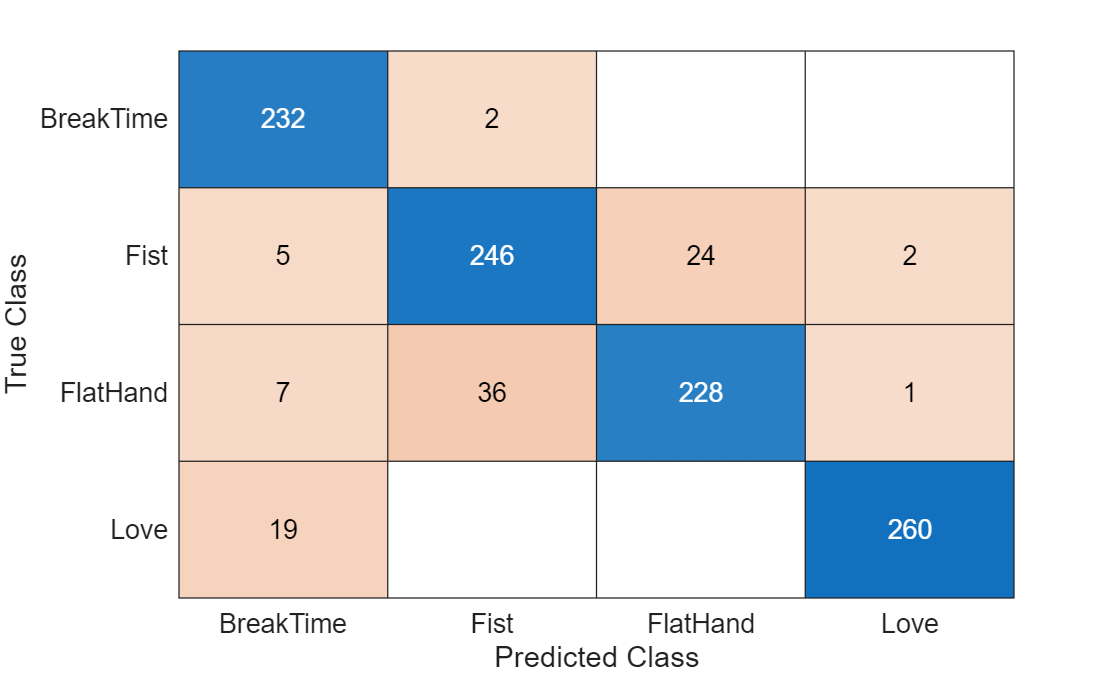

qNet = qLocal.quantize(); 

%% test the Quantized network
scoresQuantized = minibatchpredict(qNet,xTest);
YQuantized = onehotdecode(scoresQuantized,classNames,2);
confusionchart(label_Test,YQuantized);

accuracyQuantized = mean(YQuantized == label_Test) 

accuracyQuantized = 0.9096

## Interactively working with Deep Network Quantizer

deepNetworkQuantizer